# Optical image:  Principles

The purpose of this tutorial is to review the general principles of image formation.  The related tutorials, referenced in See Also, focus on the software and its parameters.  Here, we describe the ideas of image formation and that we find very compelling and illustrate them.  That makes for a long, chatty livescript which, in turn, connects to a book I am preparing.   

ieInit;

## Pinhole camera

Electromagnetic radiation is surrounds us, traveling in all directions.  The radiation we  sense with our eyes - **light** - contains a great deal of information about the objects that we navigate around, use as tools, or eat.  The image below shows an early insight about the light field surrounding us. The idea, from Leonardo's notebooks, describe a pinhole camera ([Visual Principles](https://stanford.edu/~wandell/data/papers//2021-Principles-Ashby.pdf)). The image shows that radiation from each point travels in many directions. It was Leonardo's insight that creating a small hole in a screen would select some of the rays. Simple ray tracing reveals why this forms an image on the wall.

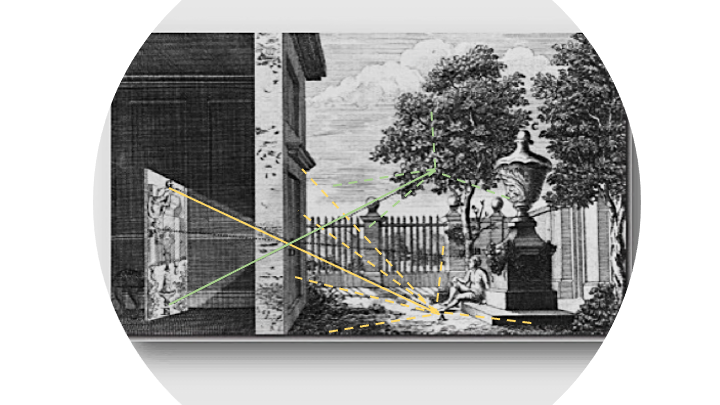

To simulate this situation requires being able to keep track of the position of the objects, the hole, and the wall's surface.  As we move the wall towards or away from the pinhole, or we change the size of the wall, the image we encode will differ.  This geometry is computable and part of the quantitative information we account for ISETCam calculations.

## Geometry

By creating a pinhole optical image (oi), we set a parameter that skips blur.  The pinhole size is 1 mm and we set the 1000 mm focal length, rather like the figure. The default distance of the scene will be 1.2m.  You can see these and other parameters both in the scene window and in the tables that I print out.

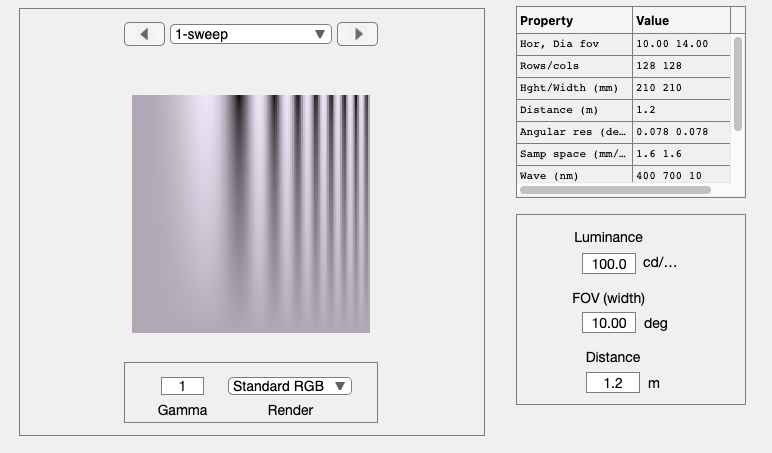

scene = sceneCreate('sweep frequency');
sceneWindow(scene);

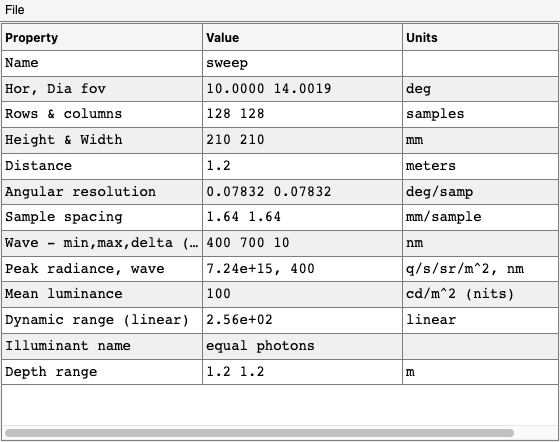

iePTable(scene); 

The scene is represented with a small number of row/col samples, spaced about 2 mm apart.  The size of the scene is about 140 x 210 mm. 

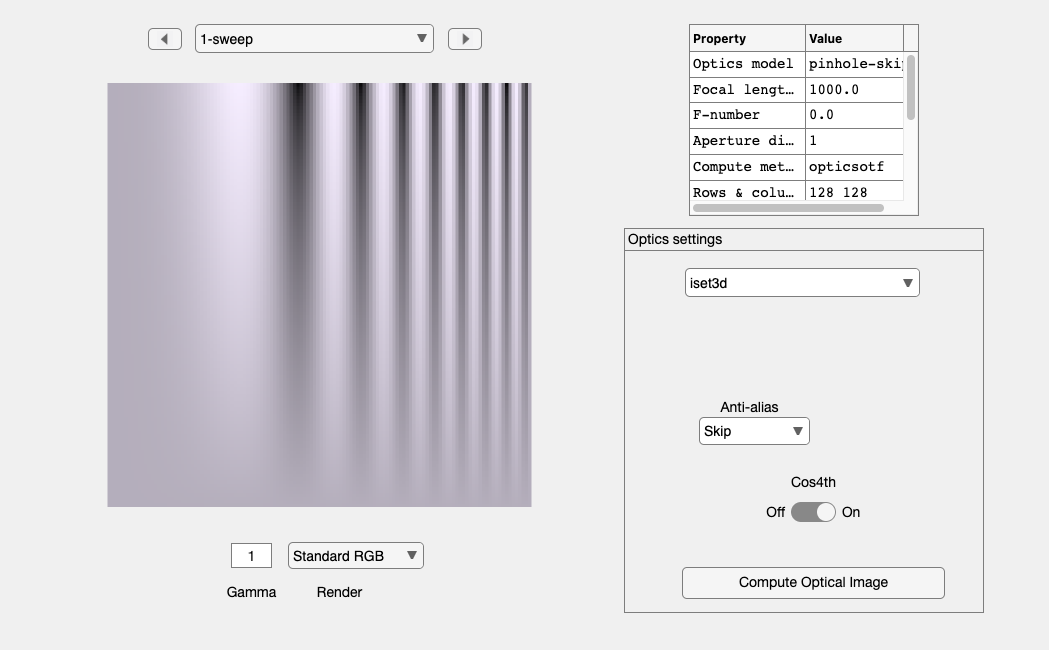

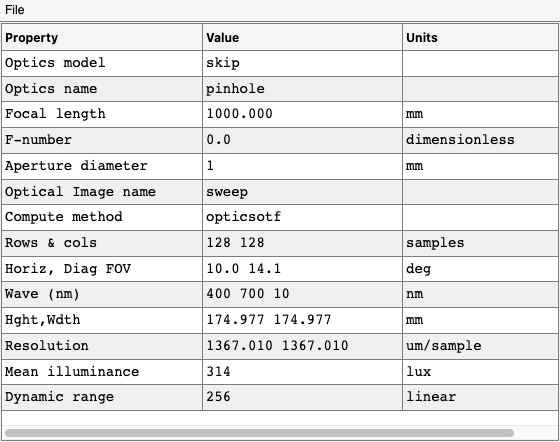

oi = oiCreate('pinhole');
oi = oiSet(oi,'optics focal length',1);
oi = oiCompute(oi,scene);
oiWindow(oi);iePTable(oi);

The image is about 116 x 174 mm and the samples are spaced about 1.8 mm apart.  

Now, suppose we change the focal length, bringing the wall closer to the pinhole.  ISETCam should update the geometry.  Let's check.

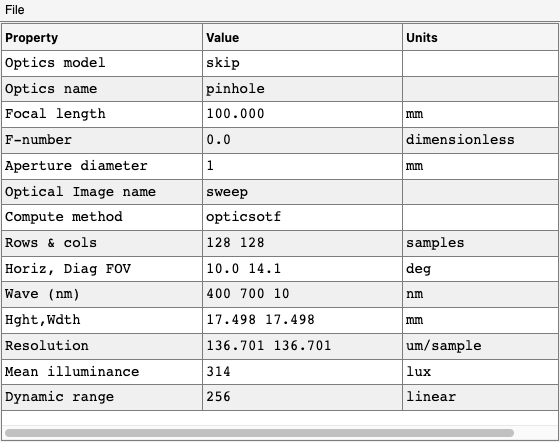

oi = oiSet(oi,'optics focal length',0.1);
oi = oiCompute(oi,scene);
iePTable(oi);

As we moved the wall closer to the pinhole, the image size shrank to 11 x 17mm and the sample spacing on the wall became smaller as well, 0.18 mm.  

There are multiple geometric properties that need to be accounted for to remain consistent. Rather than imposing this on the user, ISETCam accounts for them.  

## Shift-invariant optics

Next consider simulating a lens. A lens solves a key problem with pinhole optics:  the pinhole doesn't let much light through. The lens can have a much bigger aperture to gather more light.  It must be designed to preserve the image, making sure the rays end up in the same place.

The important point about lenses and pinholes is that they are linear systems.  This means the following: Suppose a lens forms an image of a scene, $x$.  Call this $L(x)$.  The same lens forms an image of a scene $y$, $L(y)$.  Then the image formed of the sum of the two scenes is the sum of the two images:

$L(x+y) = L(x) + L(y)$. 

Linearity means we calculate the image formed by adding up the image from each point in the scene.  We scale the point spread by the intensity of the scene, and we add together all these images.  This additive is a very general property that applies to most imaging lenses.

Under many conditions, the system can be further simplified because all the points in the scene have the same spread.  The only difference is that the point spread is mapped into a different image location. If the point spread is the same as we shift the point location, we say the system is shift invariant. Many useful calculations are performed using a shift-invariant model.  Image formation near the center of the lens for small shifts, and for either planar or distant scenes, can be usefully modeled this way.

To model a shift-invariant system, we simply need a way to represent the point spread function for each wavelength. We convert the scene radiance into an image irradiance by accounting for the geometry and adding up the wavelength-dependent point spread functions. A key description of the optics is the point spread function (PSF). A few other factors must be taken into account; we return to describe them later.

### Diffraction-limited optics

The most basic shift-invariant optics model is that of an ideal lens with a circular aperture.  There are many reasons why we would perform analyses with an ideal lens, but perhaps the most obvious is that it sets an upper limit on performance: any real lens will perform less well.

The properties of a diffraction-limited lens are entirely determined by the ratio of its focal length to the lens diameter.  This ratio is called the f/#.  The expected blurring and point spread function from a diffraction-limited lens varies with wavelength.  Here is a  calculation that illustrates the blur from such a lens.

First, let's create a simple test scene.  Grid lines with an equal energy spectrum, a 3 deg horizontal field of view.

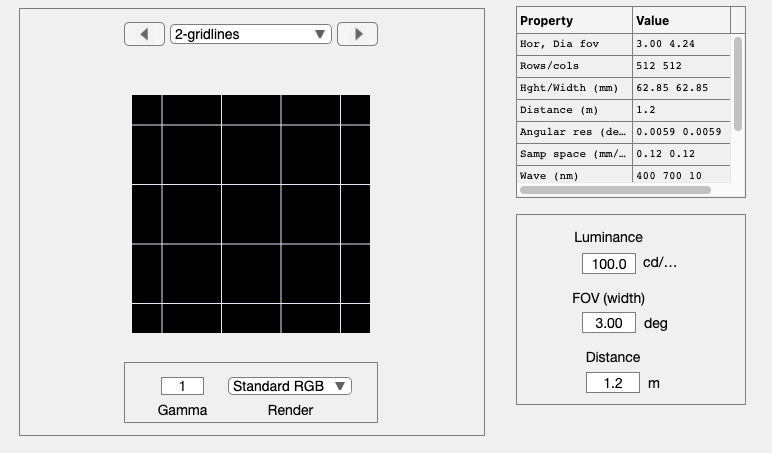

scene = sceneCreate('gridlines',512,128,'ep',3); 
scene = sceneSet(scene,'h fov',3);
sceneWindow(scene);

Next create an optical image structure with a diffraction limited lens and f/# of 8.

oi = oiCreate('wvf');
oi = oiSet(oi,'optics f number',8);

Now compute how the scene is transformed into the optical image

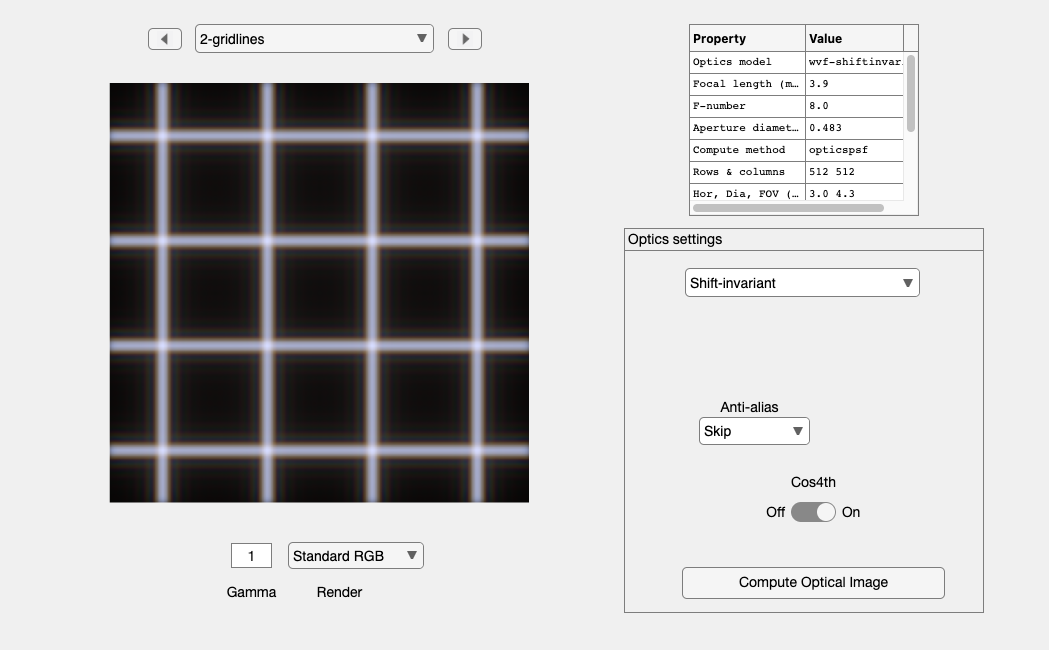

oi = oiCompute(oi,scene,'crop',true);
oiWindow(oi);

The blur depends on the wavelength.  Here are plots of the point spread function. First for 400 nm

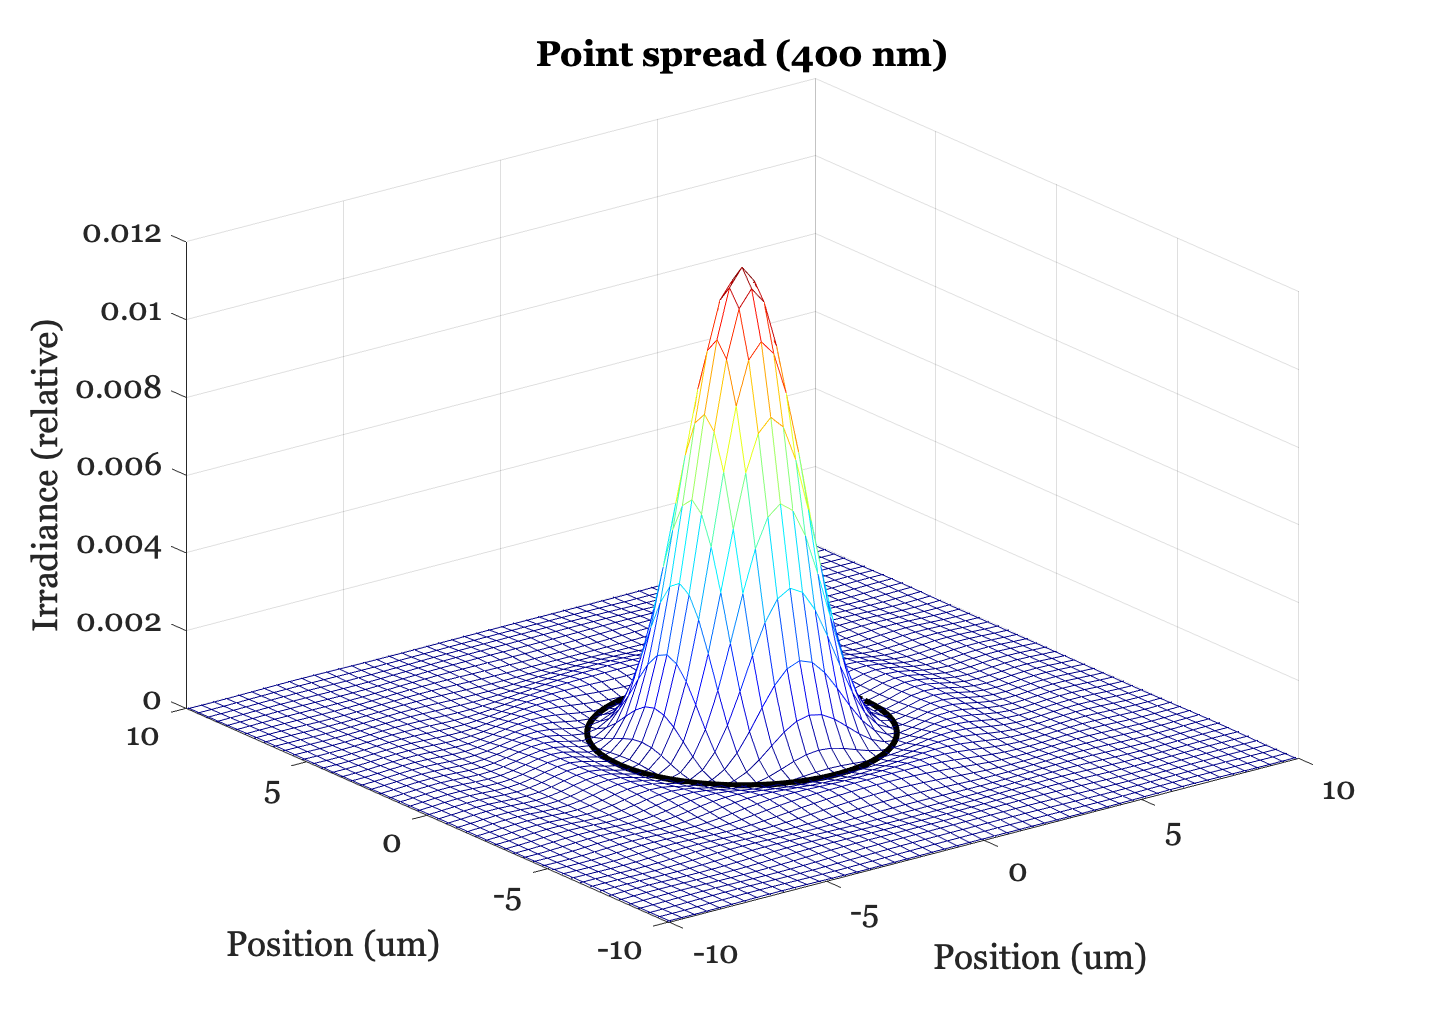

oiPlot(oi,'psf',[],400); set(gca,'xlim',[-10 10],'ylim',[-10 10]);

And now for 700 nm

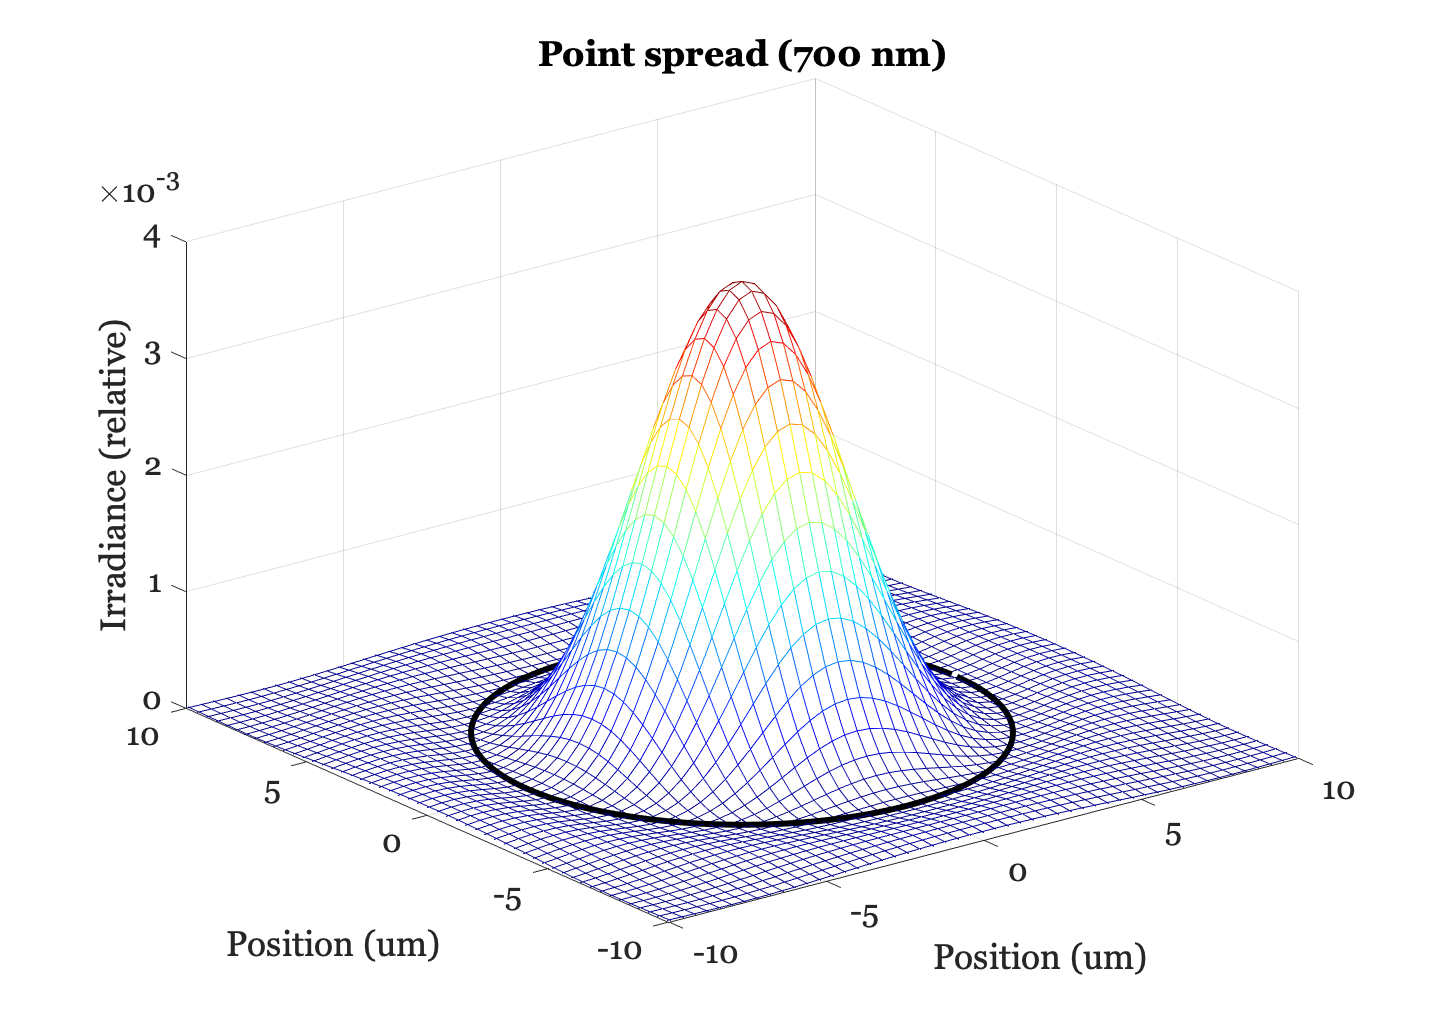

oiPlot(oi,'psf',[],700);set(gca,'xlim',[-10 10],'ylim',[-10 10]);

Finally, here is a plot of the spectral irradiance across a horizontal line in the optical image.  Notice that the oiPlot function returns the information that is in the plot in the form of a struct.  

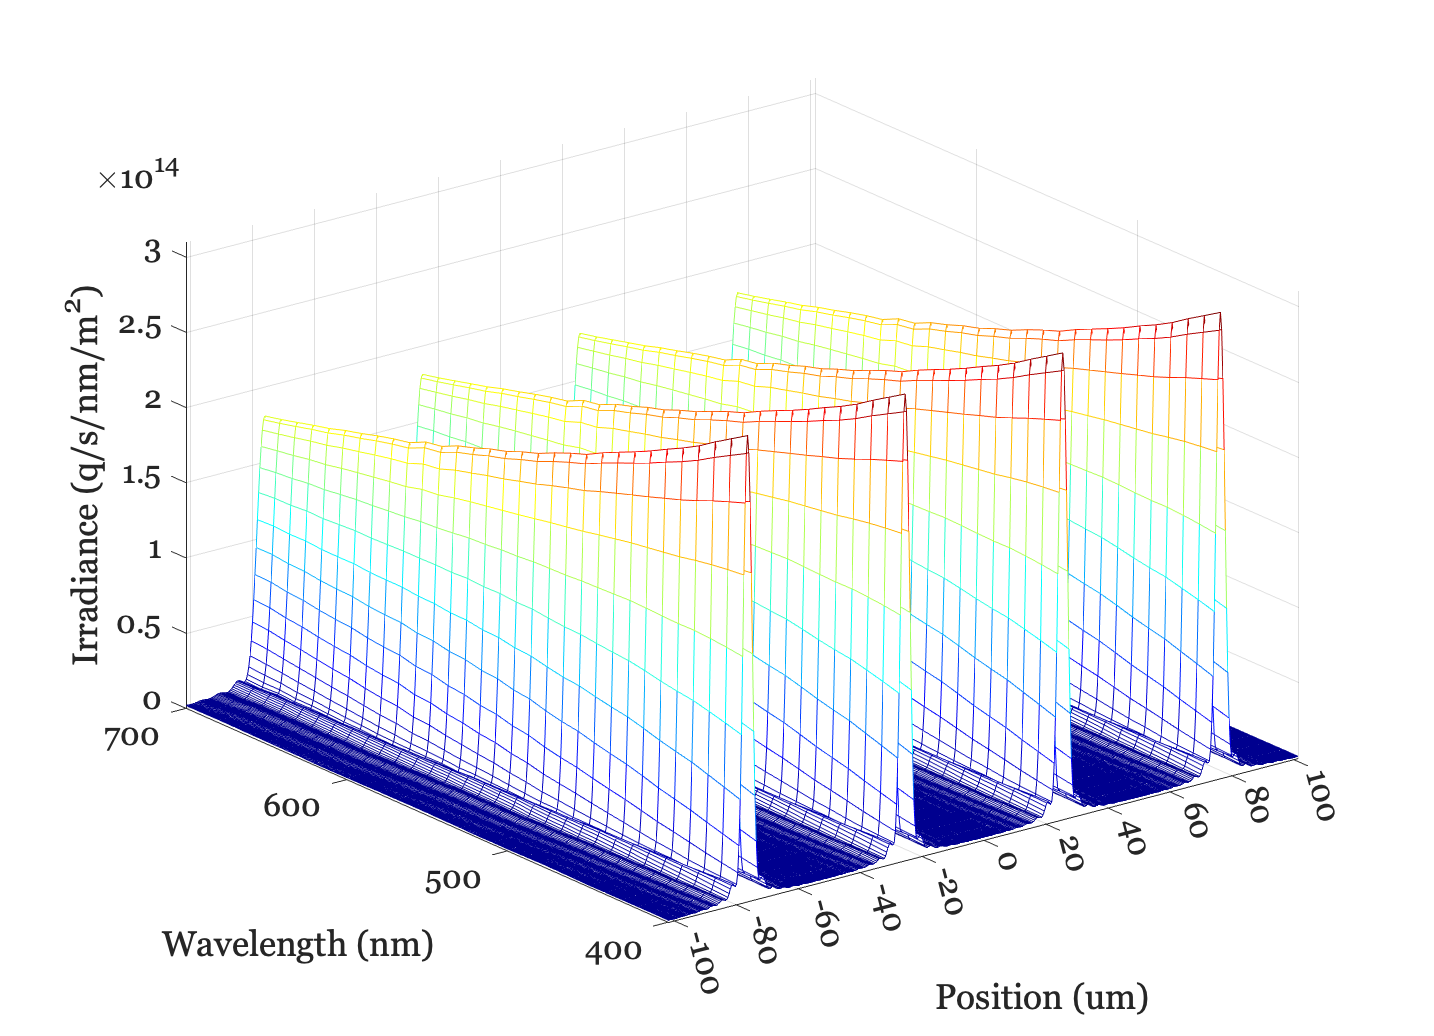

ans = struct with fields:
    roiLocs: [1 256]
       wave: [31×1 single]
        pos: [-101.6054 -101.2078 -100.8101 -100.4124 -100.0148 -99.6171 -99.2194 -98.8217 -98.4241 -98.0264 -97.6287 -97.2310 -96.8334 -96.4357 -96.0380 -95.6404 -95.2427 -94.8450 -94.4473 -94.0497 -93.6520 -93.2543 -92.8566 -92.4590 … ] (1×512 double)
       data: [31×512 double]
        cmd: 'mesh(pos,wave,data)'


oiPlot(oi,'irradiance hline',[1 256])

## Wavefront aberrations

When we created the oi, we used the command

The 'wvf' indicates that we are planning to control the properties of the shift invariant optics by specifying a wavefront aberration function.  By default, the optics is created to be perfect (diffraction limited).  It is possible to change the wavefront aberrations and in this way alter the properties of the point spread function.  The idea of the wavefront aberration function, and its parameters, are described in the tutorials t_wvfOverview and t_wvfZernike.

Here, we provide an illustration of how we can change the point spread by setting the wavefront parameters.  The first example introduces defocus into the image.  First, let's see what the lens power is in diopters.

fprintf('Lens power:  %.2f diopters \n',oiGet(oi,'optics diopters'))

Lens power:  258.88 diopters 


Next, we defocus.

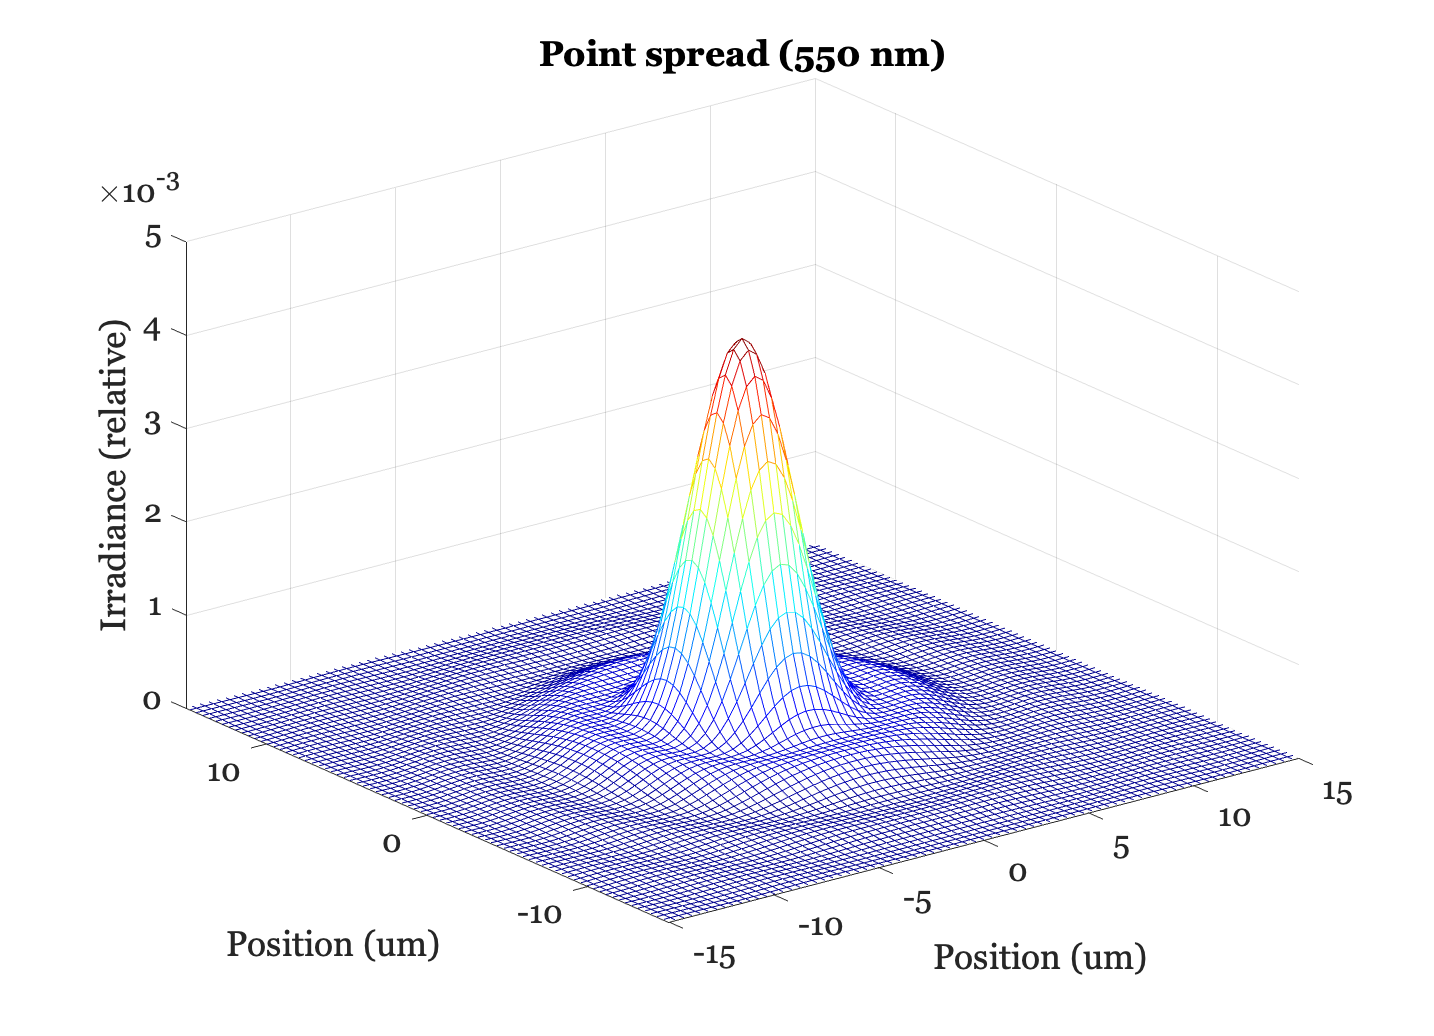

defocusD = 15;
oi = oiSet(oi,'zcoeffs',defocusD,'defocus');
oiPlot(oi,'psf 550');
set(gca,'xlim',[-15 15],'ylim',[-15 15]);

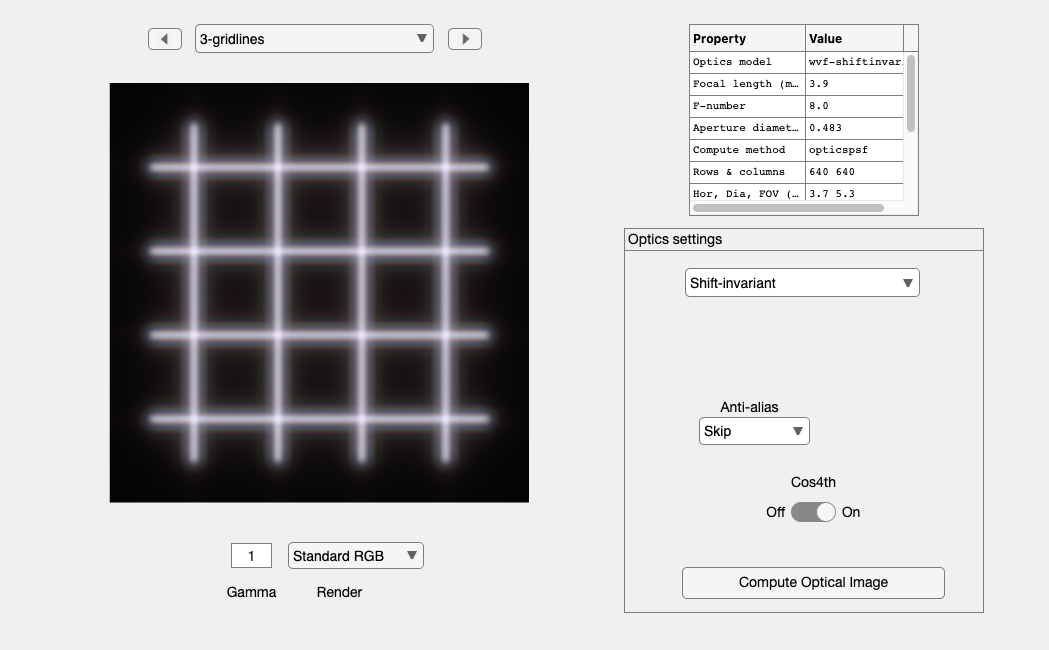

oi = oiCompute(oi,scene);
oiWindow(oi);

The point spread is wavelength dependent, so we compare again

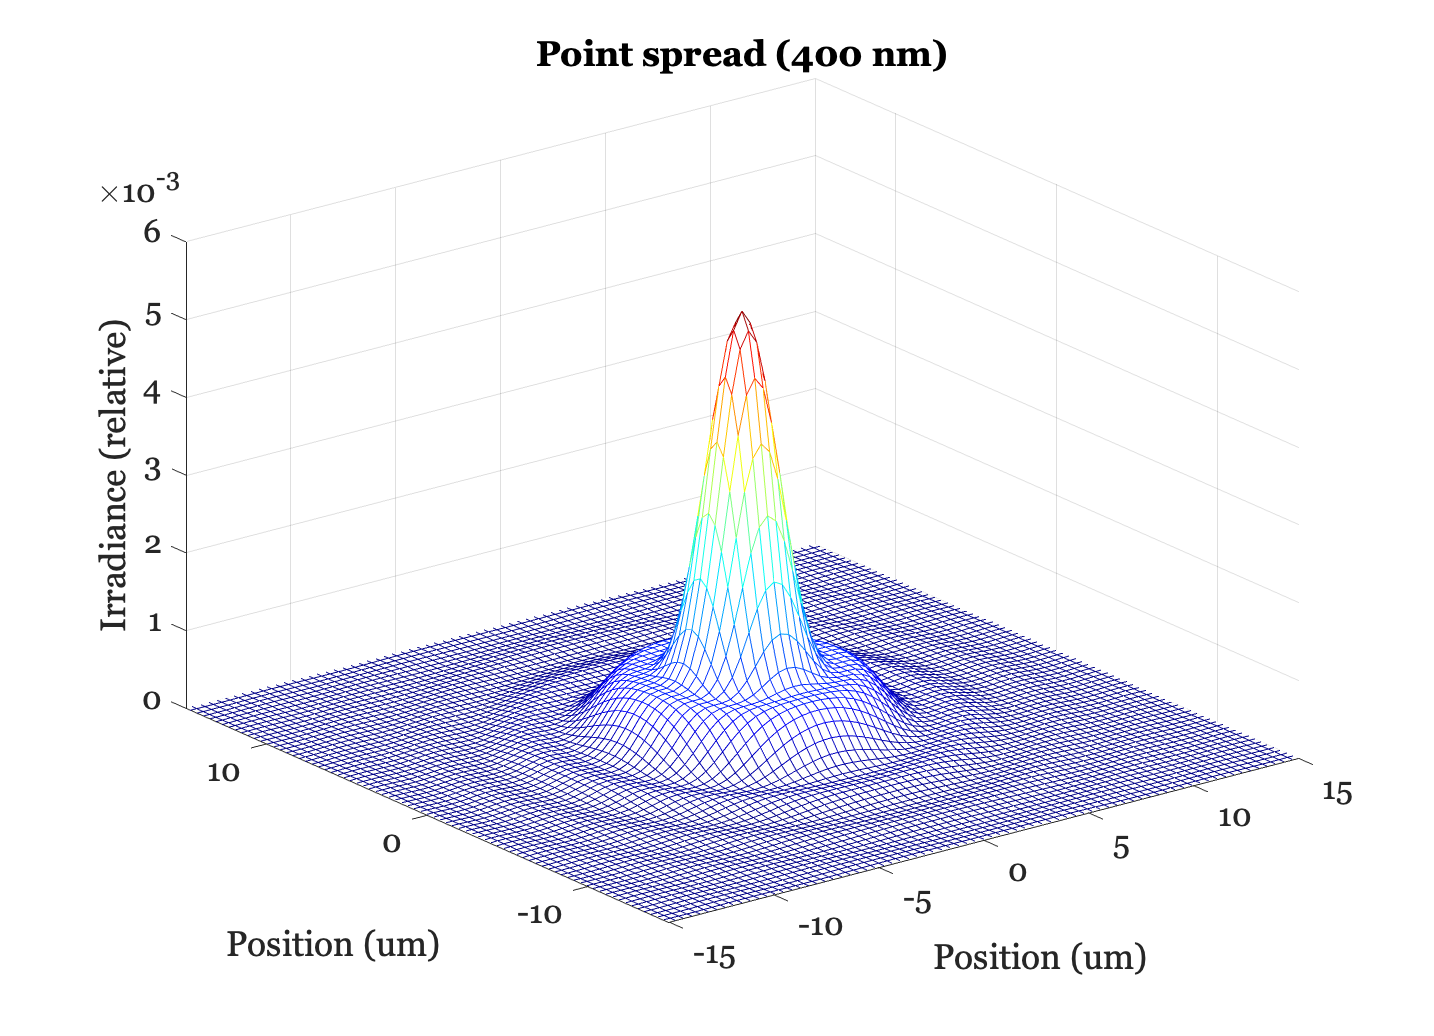

oiPlot(oi,'psf',[],400); set(gca,'xlim',[-15 15],'ylim',[-15 15]);

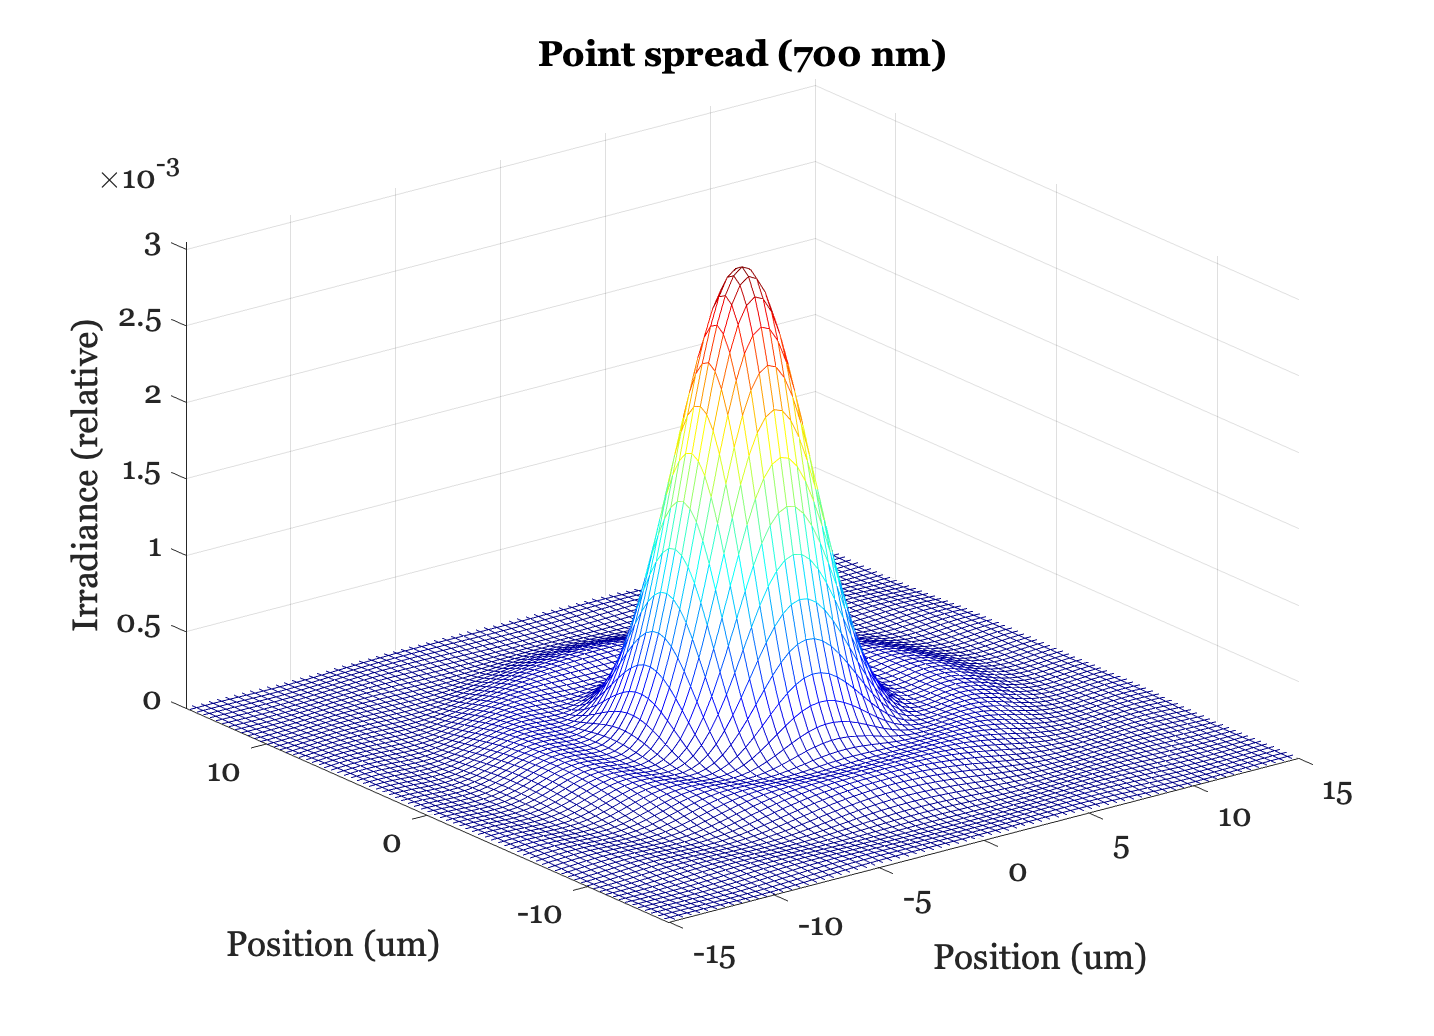

oiPlot(oi,'psf',[],700); set(gca,'xlim',[-15 15],'ylim',[-15 15]);

## Astigmatism

(To just run this cell, make sure to recreate the oi first.  And run an oiCompute).

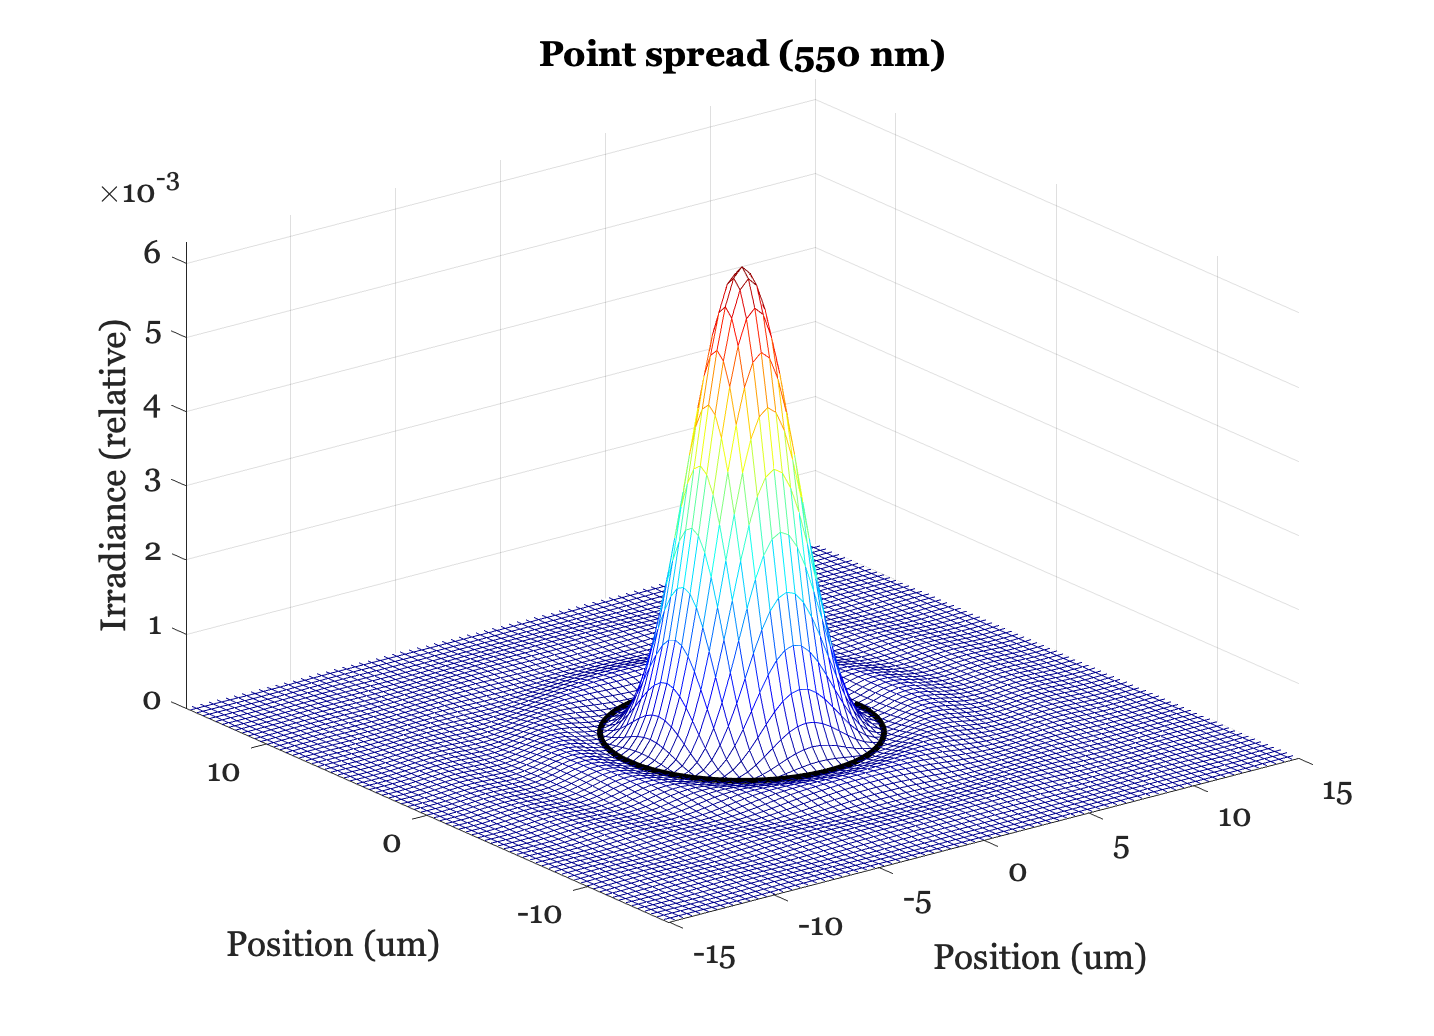

zcoeffsCell = {'defocus','vertical_astigmatism','oblique_astigmatism'};
defocusD = 0; vertical_astigmatism = 0; oblique_astigmatism = 0;
oi = oiSet(oi,'zcoeffs',[defocusD,vertical_astigmatism,oblique_astigmatism],zcoeffsCell);
% oi = oiCompute(oi,scene);
oiPlot(oi,'psf 550'); set(gca,'xlim',[-15 15],'ylim',[-15 15]); drawnow;

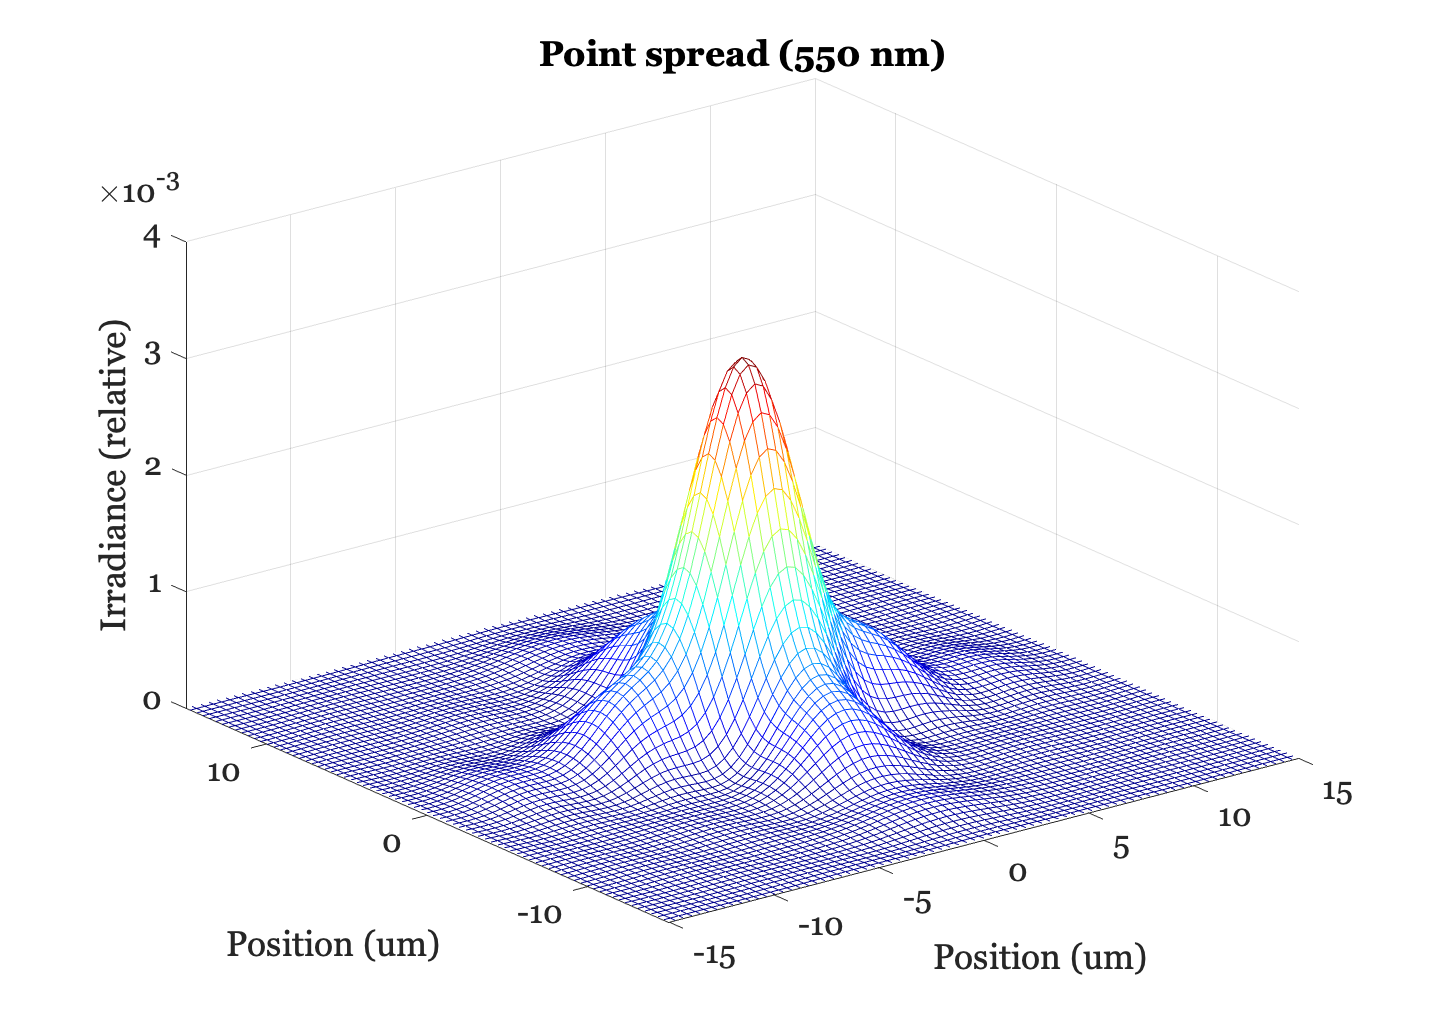

defocusD = 0; vertical_astigmatism = 20; oblique_astigmatism = 0;
oi = oiSet(oi,'zcoeffs',[defocusD,vertical_astigmatism,oblique_astigmatism],zcoeffsCell);
oiPlot(oi,'psf 550'); set(gca,'xlim',[-15 15],'ylim',[-15 15]); drawnow;

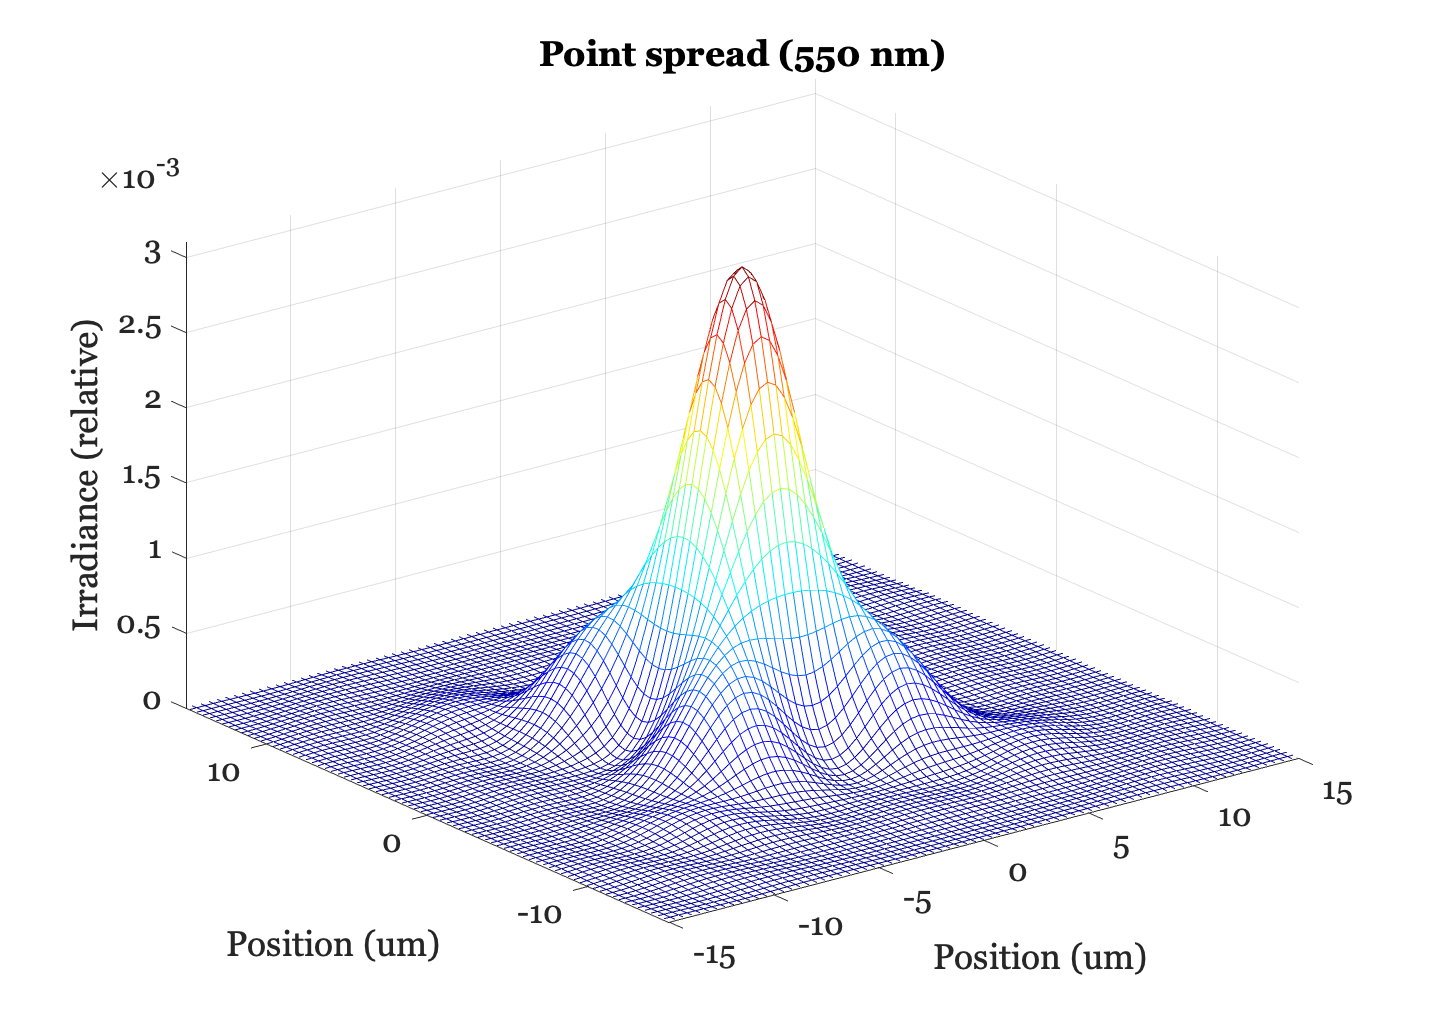

defocusD = 0; vertical_astigmatism = 0; oblique_astigmatism = 20;
oi = oiSet(oi,'zcoeffs',[defocusD,vertical_astigmatism,oblique_astigmatism],zcoeffsCell);
oiPlot(oi,'psf 550'); set(gca,'xlim',[-15 15],'ylim',[-15 15]); drawnow;

## Aperture (apodization)

Finally, the shape of the aperture can have a significant impact on the image.  We have been assuming that the aperture is circular, and in this example we will create an aperture that's a polygon.

First, create a high dynamic range scene.  This will reveal the details of the point spread clearly.

scene = sceneCreate('hdr image',...
    'dynamic range',5,...
    'patch shape','circle','npatches',5,'patch size',10);

Now create an oi, and notice that we can ask for the wavefront structure to be returned at the time of creation.

[oi,wvf] = oiCreate('wvf');

This sets the sample density of the aperture image. We use a high sampling density to show the details clearly.

wvf = wvfSet(wvf,'npixels',512);

We will create apertures with several different polygon sides, or with a circular shape.

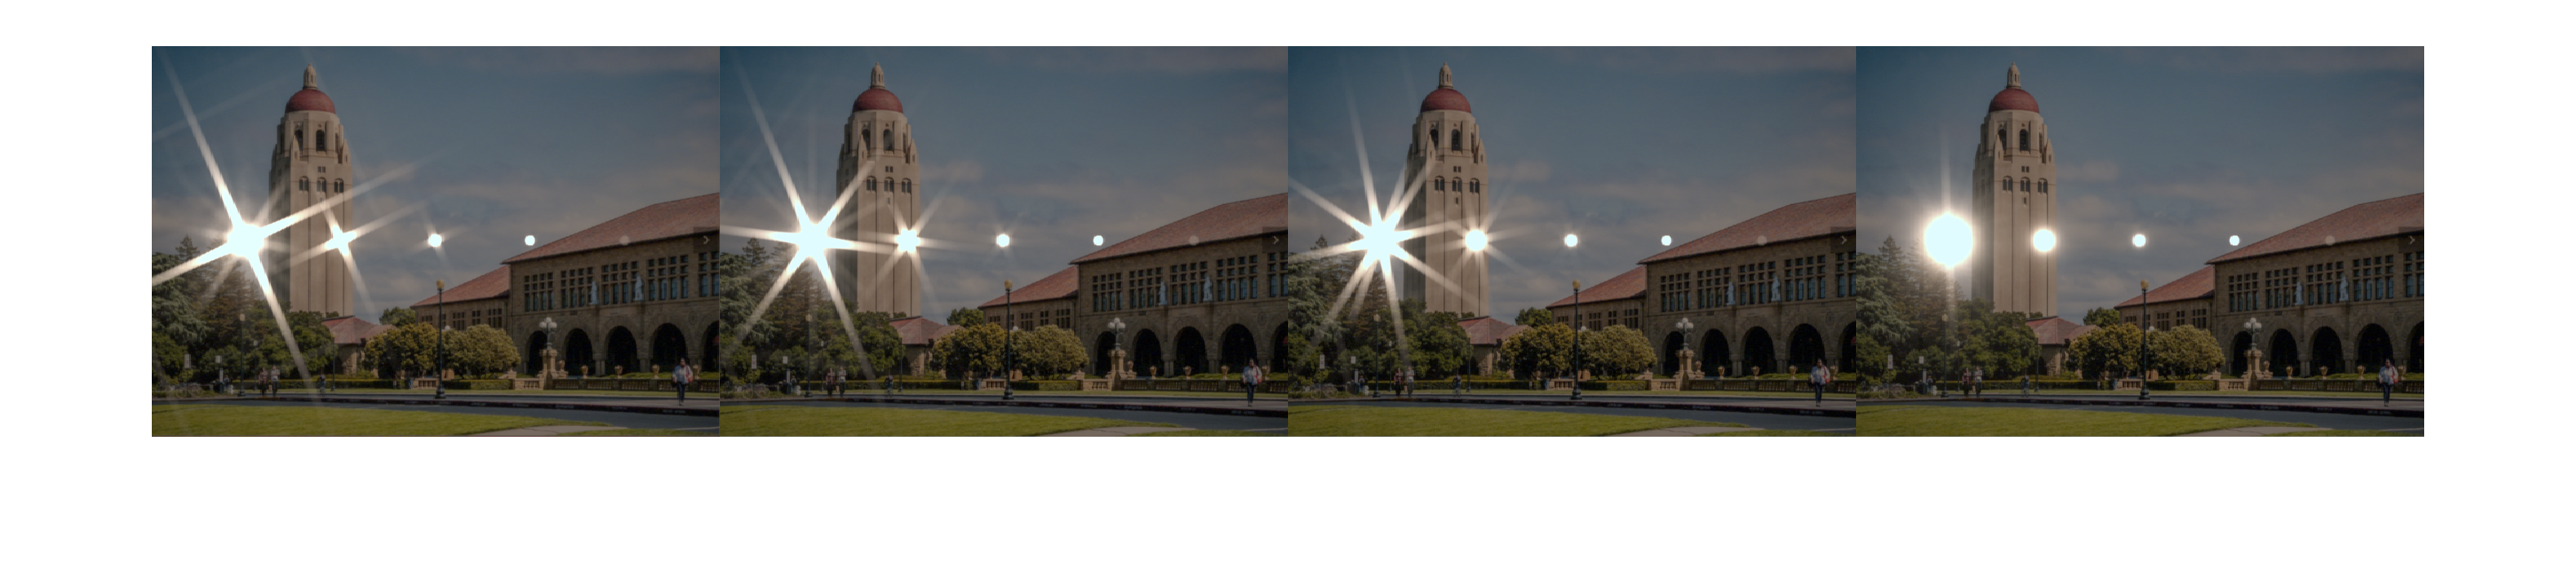

nsides = [4 6 8 0];   % 0 means a circular shape.
img = cell(numel(nsides),1);
sensor = [];

for ii = 1:numel(nsides)
    [aperture, params] = wvfAperture(wvf,'nsides',nsides(ii),...
        'dot mean',10, 'dot sd',5, 'dot opacity',0.5,'dot radius',5,...
        'line mean',10, 'line sd', 5, 'line opacity',0.5,'linewidth',2);

    oi = oiSet(oi,'fnumber',1.5);
    oi = oiSet(oi,'focal length',4.38e-3,'m');

    oi = oiCompute(oi, scene,'crop',true,'pixel size',3e-6,'aperture',aperture);

    oi = oiAdjustIlluminance(oi, 100);
    
    % To visualize, we used the image processor window. This is just to
    % show off.  We could have stopped at the oi.  I just want you to know
    % there are sensors and image processing.
    if isempty(sensor)
        % First time through, create a sensor using this function.
        [ip,sensor] = piRadiance2RGB(oi,'etime',1/10);
    else
        % Next time, use the sensor
        sensor = sensorCompute(sensor,oi);
        ip = ipCompute(ip,sensor);
    end

    img{ii} = ipGet(ip,'srgb');    
end

montage(img,'Size',[1, numel(nsides)]);